clear
clc

J = 0.018; % moment of inertia of the rotor kg.m^2
b = 0.00 % (UKNOWN) motor viscous friction constant N.m.s 

b = 0

Km = 0.12605 % electromotive force constant V/rad/sec

Km = 0.1261

Kt = 0.126 % motor torque constant N.m/Amp

Kt = 0.1260

R = 0.01 % electric resistance Ohm

R = 0.0100

L = 0.0550 % electric inducance H

L = 0.0550


A = [-b/J   Km/J
    -Km/L   -R/L];
B = [0
    1/L];
C = [1   0];
D = 0;
motor_ss = ss(A,B,C,D)


motor_ss =
 
  A = 
            x1       x2
   x1        0    7.003
   x2   -2.292  -0.1818
 
  B = 
          u1
   x1      0
   x2  18.18
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




s = tf('s');
P_motor = Km/((J*s+b)*(L*s+R)+Km^2)


P_motor =
 
                0.126
  ---------------------------------
  0.00099 s^2 + 0.00018 s + 0.01589
 
Continuous-time transfer function.



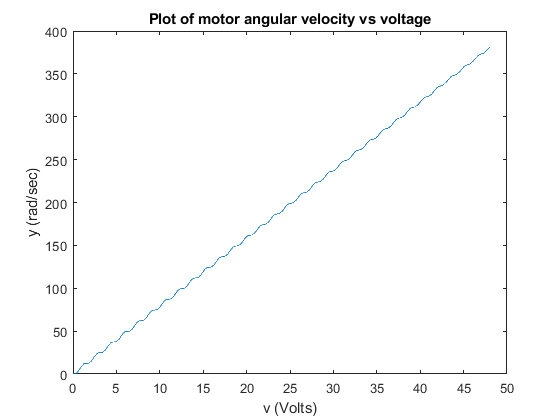


x0 = [0 0]; % Zero rotatial speed, zero electric current
h = 0.01;
v_max = 48;
% Pre-allocate value for u
u = linspace(0, v_max, (v_max+h)/h);
x = zeros(2,v_max/h);
x(:,1) = x0; % Assign initial values
% x evaluated over 0 <= V <= 48
for v_ind = 1:v_max/h
    x(:,v_ind+1) = x(:,v_ind) + h*(A*x(:,v_ind)  + (B*u(v_ind)));
end 

% Evaluate y with solved x
motor_angular_velocity = C*x;

v = 0:h:v_max; % voltage for plot
plot(v,motor_angular_velocity(:));
ylabel("y (rad/sec)");
xlabel("v (Volts)");
title("Plot of motor angular velocity vs voltage");

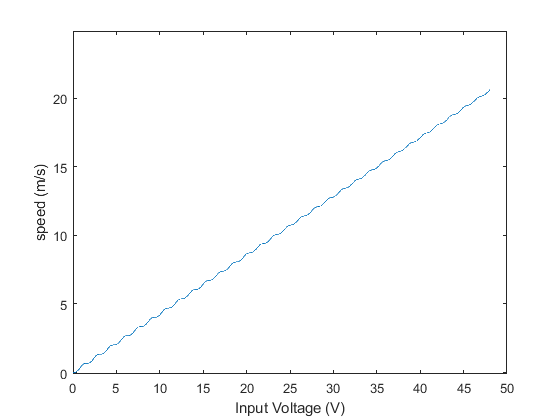


radius = 0.27/2; % wheel
gearRatio = 2.5;
gear_angular_velocity = motor_angular_velocity/2.5;
linear_velocity = gear_angular_velocity*radius;

figure
plot(v, linear_velocity);
ylabel("speed (m/s)");
xlabel("Input Voltage (V)");